TATTU Pro Model:  TAPRAS22K1225X

power_TAPRAS22K1225X() defines the design parameters for the TATTU Pro TAPRAS22K1225X battery.

### Calling Sequence:

- [power] = power_TAPRAS22K1225X()

#### Inputs:

- none

#### Outputs:

- power - power data structure with TATTU-Pro TAPRAS22K1225X battery properties

TATTU Pro is suitable for multiple drone systems, 12S1P, 22Ah battery.

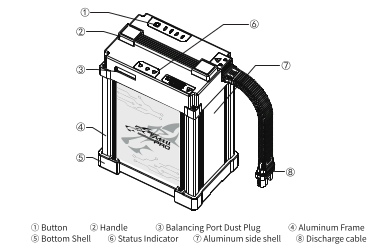

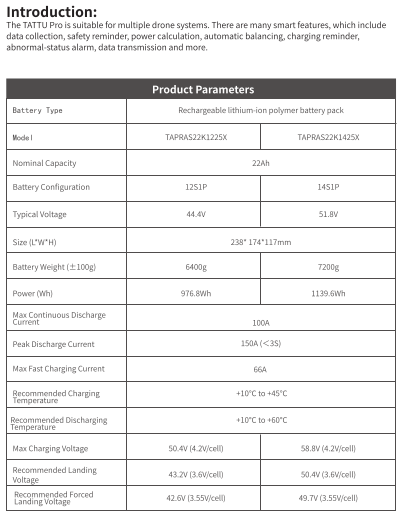

function [power] = power_TAPRAS22K1225X()
    % energy/power data
    power.type = 'battery';                     % power type
    power.energy = 976.8;                       % battery energy [Wh]
    power.capacity = 22000;                     % battery capacity [mAh]
    power.dischargeCurrentMax = 100;            % max continuous discharge current [A]
    power.C = power.dischargeCurrentMax/(power.capacity/1000);  % battery C-rating
    power.dischargeCurrentPeak = 150;           % peak discharge current [A]
    power.Vnom = 44.4;                          % battery nominal voltage [V]
    power.Vmin = 43.2;                          % battery minimum voltage [V]
    % size data
    power.weight = 6.4;                         % battery weight [kgf]
    g = 9.80665;                                % accel due to gravity [m/s^2]
    power.mass   = power.weight/g;              % battery mass [kg]
    power.length = 238;                         % battery length [mm]
    power.width = 174;                          % battery width [mm]
    power.height = 117;                         % battery height [mm]
    % coordinate system data
    weight = power.weight;                      % local weight
    length = power.length;                      % local length
    width  = power.width;                       % local width
    height = power.height;                      % local height
    power.origin = (1/2)*[length;width;height]; % battery local coord system origin           
    power.cg = zeros(3,1);                      % battery global coord system origin
    power.n1 = zeros(3,1);                      % battery global direction vector along length
    power.n2 = zeros(3,1);                      % battery global direction vector along width
    % principal mass moments of inertia estimate, Ixy=Iyz=Izx=0.0
    Ixx = (1/12)*(weight/g)*(width^2 + height^2);   % Ixx
    Iyy = (1/12)*(weight/g)*(length^2 + height^2);  % Iyy
    Izz = (1/12)*(weight/g)*(length^2 + width^2);   % Izz
end